# AUTORePO structure

In this example, we continue to explore the AUTORePO structure storing multiple bifurcation diagrams. Specifically, we will illustrate how to integrate the information of 1P- and 2P-BD in the same window. The ODE model used for this purpose is the standard Hodgkin Huxley presented in [1]. The ODEs are the followings,

$\begin{array}{l}
c\dot{v} =I_0 +I_s \left(t\right)-I_{\textrm{Na}} \left(v,m,h\right)-I_K \left(v,n\right)-I_L \left(v\right),\\
\;\dot{m} =\alpha_m \left(v\right)\left(1-m\right)-\beta_m \left(v\right)m,\\
\;\dot{h} =\alpha_h \left(v\right)\left(1-h\right)-\beta_h \left(v\right)h,\\
\;\dot{n} =\alpha_{n\;} \left(v\right)\left(1-n\right)-\beta_n \left(v\right)n\ldotp 
\end{array}$   (1)

The `.ode` file that we are going to use for this demo is a modified version of the one that you can find among the documentation of XPPAUT [2].

[1] Hodgkin AL, Huxley AF. *A quantitative description of membrane current and its application to conduction and excitation in nerve*. The Journal of Physiology, 1952.

[2] Ermentrout B. *Simulating, Analyzing, and Animating Dynamical Systems: A Guide to XPPAUT for Researchers and Students. *SIAM, 2002.

## ENVIROMENT SET-UP

We set up the environment by cleaning the workspace and the command window of the current MATLAB session and by closing all the opened figures. Then, we proceed by importing the folders and subfolders where the main XPPLORE functions are stored.

% ENVIRONMENT
clear all; close all; clc;

% IMPORT
addpath(genpath('../../Function_Visualization'))
addpath(genpath('../../Function_XPPAUT'))

## MODEL STRUCTURE

We use the function *Func_ReadModel *to read the model.

% MODEL
M = Func_ReadModel('hh.ode');

## AUTORePO

We load the file `hh.auto` by using the function *Func_ReadDiagram*. As it could be seen by executing the following chunk of code, the `.auto` file stores three BDs. These are:

- `BD1_i0`: It is a 1P-BD computed by using, as main bifurcation parameter, the applied current `i0`.

- `BD2_i0_gk`: This is a 2P-BD where the bifurcation parameters are `i0` and `gk`.

- `BD3_i0`: It is a 1P-BD like `BD1_i0` computed with respect to `i0`. This bifurcation diagram has been computed for a different value of `gk` compared to the one of `BD1_i0`.

First of all, as we were mentioning in the past demos, the bifurcation diagrams name's interger value is an incremental index that is not related with the number of bifurcation parameters used. This demo aims to present a different visualization to interpret the movement of the bifurcations along a second continuation parameter.

% AUTOREPO
AR = Func_ReadAutoRepo(M,'hh.auto');

AR:
    Parsing settings ...completed!
    Parsing hot parameters ...completed!
    Parsing branches & labelled points ...completed!
    Parsing Special Solutions...completed!

    Summary:
        1P-BD - Name: BD1_i0 - Main: i0
        2P-BD - Name: BD2_i0_gk - Main: i0 - Secondary: gk
        1P-BD - Name: BD3_i0 - Main: i0


## 1P-BD & 2P-BD visualization

We start by visualizing both the 1P- and the 2P-BDs one close to the other. This type of visualization might be misleading and, for entry level students, dealing with the movement of bifurcations for the first time is far from being intuitive. We create a split window using the *tiledlayout* and the *nexttile *functions implemented in MATLAB. Please note that, you can still use the function *Func_FigStyle *to apply the same style to both tiles!

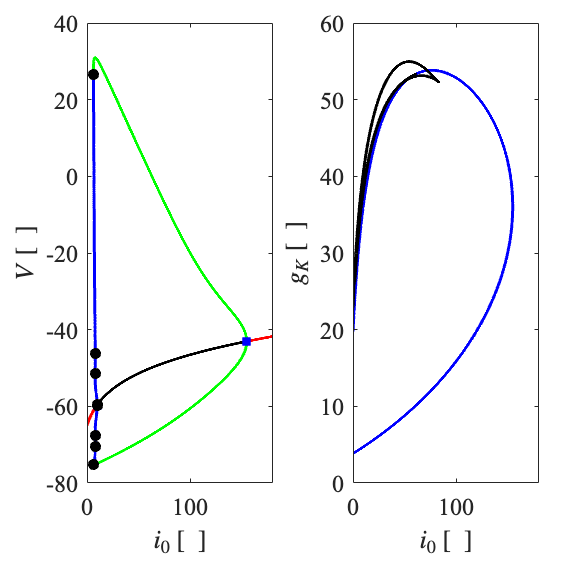

% VISUALIZATION
fig = figure();

tiledlayout(1,2,'TileSpacing','compact','Padding','compact')

nexttile()
Func_VisualizeDiagram(M,AR.BD1_i0)
Func_VisualizeLabPoints(M,AR.BD1_i0)

xlabel('$i_0$ [\ ]','interpreter','latex'), xlim([0  180])
ylabel('$V$ [\ ]','interpreter','latex')  , ylim([-80 40])

nexttile()
Func_VisualizeDiagram(M,AR.BD2_i0_gk)

xlabel('$i_0$ [\ ]','interpreter','latex'), xlim([0 180])
ylabel('$g_K$ [\ ]','interpreter','latex'), ylim([0 60])

Func_FigStyle(fig)

As you can notice, the figure seems to be squished horizontally. This happens beacuse the deafult style settings format the figure to be 10 cm x 10 cm. For this reason, we must interveene over the figure size in the style option structure by increasing the figure's width. Hence, we load the default style settings with the command *Func_DOF* (which is an acronym standing for Default Option for Figures) and we manipulate the `width` fields. If you want to use a different unit of measure for lengths, then you can change it by manipulating the `units` field of the previous option structure. Keep in mind that, when you change the unit of measure, all the measures that are currently stored in the structure are not automatically updated.

opts = Func_DOF('width',20);

Now, we can visualize again the previous charts. To pass the costumize option structure to the function *Func_FigStyle,* you have to use the name-valued argument `OPTIONs`. Now, you can notice that the figure has enought space to visualize the content properly.

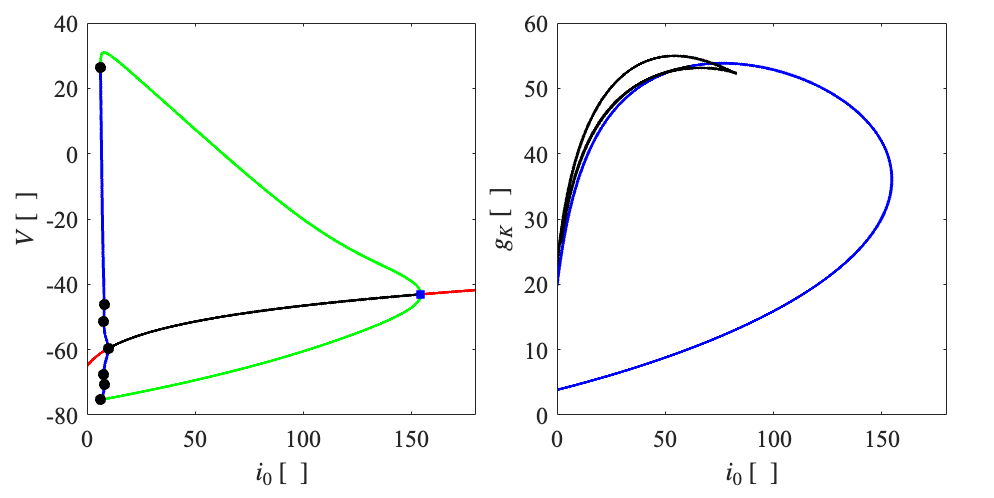

% VISUALIZATION
fig = figure();

tiledlayout(1,2,'TileSpacing','compact','Padding','compact')

nexttile()
Func_VisualizeDiagram(M,AR.BD1_i0)
Func_VisualizeLabPoints(M,AR.BD1_i0)

xlabel('$i_0$ [\ ]','interpreter','latex'), xlim([0  180])
ylabel('$V$ [\ ]','interpreter','latex')  , ylim([-80 40])

nexttile()
Func_VisualizeDiagram(M,AR.BD2_i0_gk)

xlabel('$i_0$ [\ ]','interpreter','latex'), xlim([0 180])
ylabel('$g_K$ [\ ]','interpreter','latex'), ylim([0 60])

Func_FigStyle(fig,'OPTIONs',opts)

## 2P-BD & 1P-BD integration: 2D visualization

In the following, we will show how to integrate the 1P- and the 2P-BD in the same window. First of all, we show a planar visualization, where the chart presents along the x-axis the main bifurcation parameter `i0,` while over the y-axis the secondary bifurcation parameter `gk`. These two variables used as x- and y-coordinates of the BDs is the natural set-up for the 2P-BD, but it is not the one for the 1P-BD. Therefore, we should use the functions *Func_VisualizeDiagram* and *Func_VisualizeLabPoints* by specifying the two coordinates, `i0` and `gk`. As you can see in the following figure, the 1P-BD is visualized as a simple line. This isn't surprising, in fact it is a 1P-BD. 

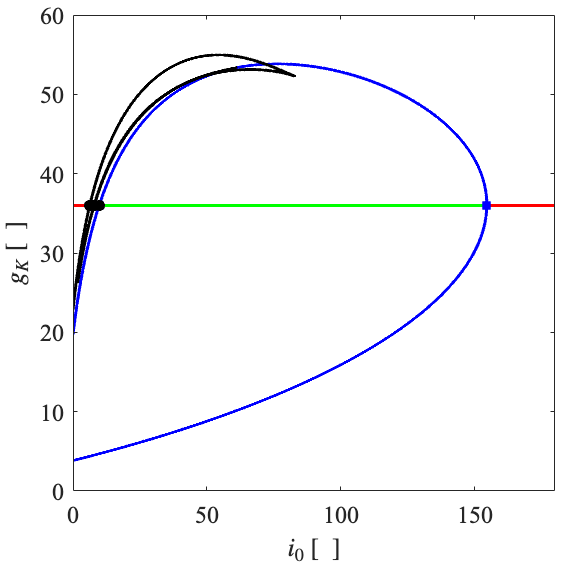

% VISUALIZATION
fig = figure();

Func_VisualizeDiagram(M,AR.BD2_i0_gk)
Func_VisualizeDiagram(M,AR.BD1_i0,'VAR',{'i0','gk'})
Func_VisualizeLabPoints(M,AR.BD1_i0,'VAR',{'i0','gk'})

xlabel('$i_0$ [\ ]','interpreter','latex'), xlim([0 180])
ylabel('$g_K$ [\ ]','interpreter','latex'), ylim([0 60])

Func_FigStyle(fig)

## 2P-BD & 1P-BD integration: 3D visualization

In the following chunk of code, we combine the 1P- and the 2P-BD through a three-dimensional plot. In this case, we set the *VAR* optional field to `{'i0','gk','v'}`.

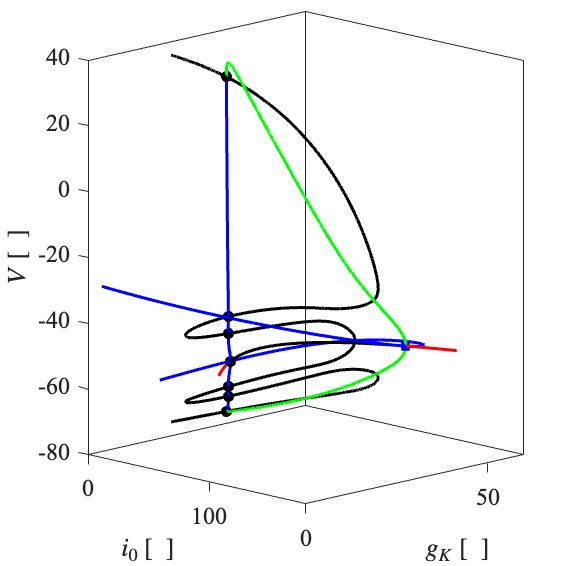

% VISUALIZATION
fig = figure();

Func_VisualizeDiagram(M,AR.BD2_i0_gk,'VAR',{'i0','gk','v'})
Func_VisualizeDiagram(M,AR.BD1_i0   ,'VAR',{'i0','gk','v'})
Func_VisualizeLabPoints(M,AR.BD1_i0 ,'VAR',{'i0','gk','v'})

xlabel('$i_0$ [\ ]','interpreter','latex'), xlim([0 180])
ylabel('$g_K$ [\ ]','interpreter','latex'), ylim([0  60])
zlabel('$V$ [\ ]','interpreter','latex'),   zlim([-80 40])

view(45,10)

Func_FigStyle(fig)

## 2P-BD & 1P-BDs integration: 3D visualization

In the **AUTORePO** section, we noticed that the AR structure presents 3 BDs. Specifically, `BD3_i0` is the same BD of `BD1_i0` but computed for a different value of `gk`. Therefore, we can visualize them all together to interpret better the movement of the different bifurcation points as the parameter `gk` is changed. Obviously, the figure is static, but you can open it by clicking over the arrow on the upper-right corner of this `.mlx` file. Now, you can freely rotate it and have a better sense of what happens as `gk` is begin changed.

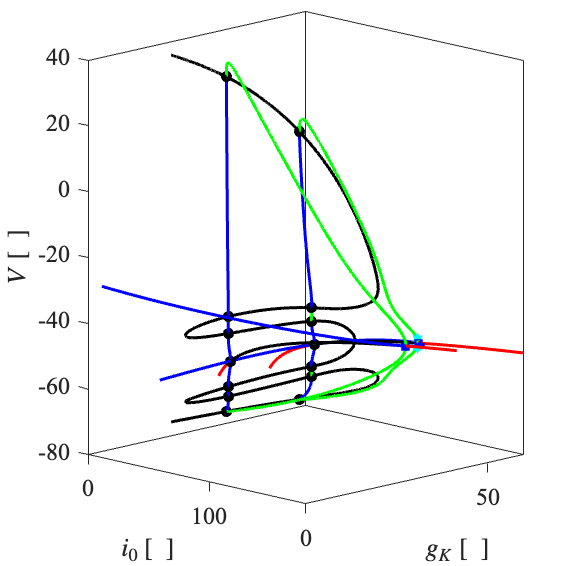

fig = figure();

Func_VisualizeDiagram(M,AR.BD2_i0_gk,'VAR',{'i0','gk','v'})
Func_VisualizeDiagram(M,AR.BD1_i0   ,'VAR',{'i0','gk','v'})
Func_VisualizeDiagram(M,AR.BD3_i0   ,'VAR',{'i0','gk','v'})
Func_VisualizeLabPoints(M,AR.BD1_i0 ,'VAR',{'i0','gk','v'})
Func_VisualizeLabPoints(M,AR.BD3_i0 ,'VAR',{'i0','gk','v'})

xlabel('$i_0$ [\ ]','interpreter','latex'), xlim([0 180])
ylabel('$g_K$ [\ ]','interpreter','latex'), ylim([0  60])
zlabel('$V$ [\ ]','interpreter','latex'),   zlim([-80 40])

view(45,10)

Func_FigStyle(fig)